clear
L = 1;
f = @(x) x^2;

precision = 1000;
x = linspace(-4*L, 4*L, precision)';

fF = ones([precision 1]) * L^2 / 3;
fS = zeros([precision 1]);

N = 100;
for n = 1:N
    fF = fF + ( 4 * L^2 * (-1)^n / (n^2 * pi^2) ) * cos(n * pi * x / L);
    fS = fS - ( (2 * L^2 * ((-1)^n * (n^2 * pi^2 - 2) + 2)) / (n^3 * pi^3) ) * sin(n * pi * x / L);
end

fC = fF;
figure
fplot(f, [-L L], 'k-')

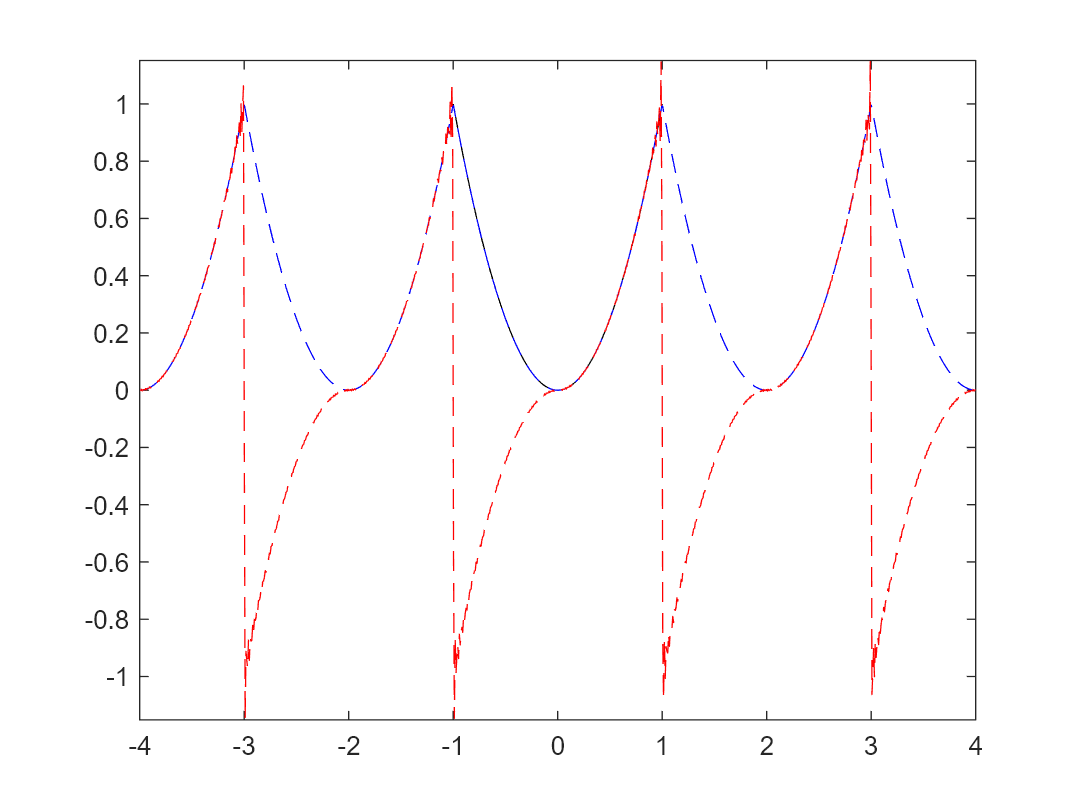

hold on
plot(x, fC, 'b--')
plot(x, fS, 'r--')
hold off